close all; clear all; clc

# Control Moment Gyroscope Simulation

## Description

This file generates a simulation for a spacecraft (modelled as an inertial body) floating in space. The spacecraft (shown in Figure 1) can change pose (attitude) by actuating it's four control moment gyroscopes (CMG). The CMG's are aligned in a pyramid configuration, as shown in Figure 2.

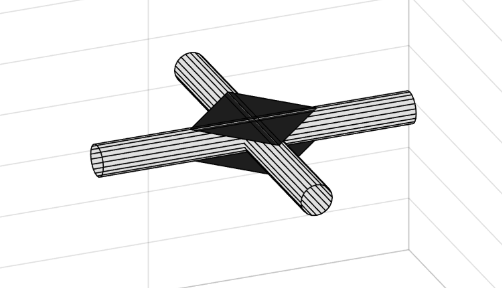

**Figure 1: **Visual Model of Spacecraft

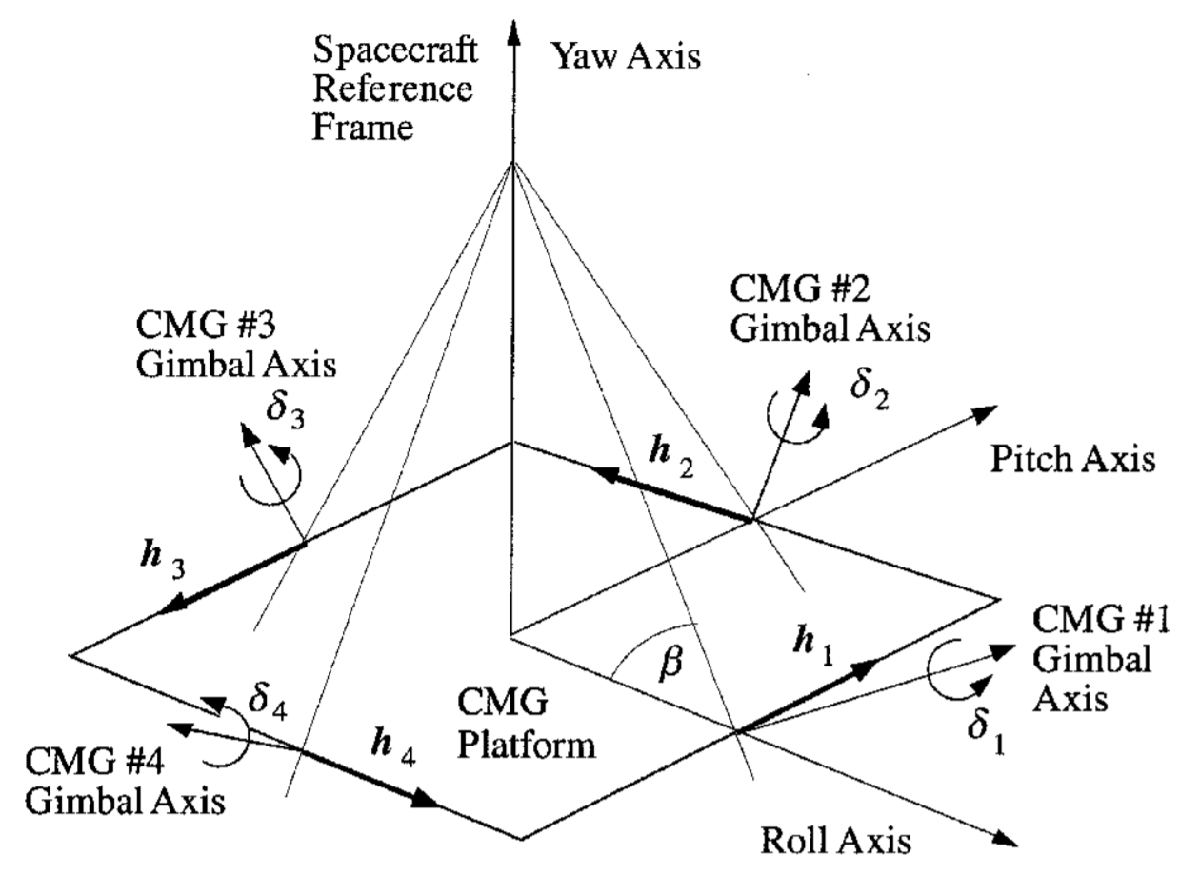

**Figure 2:** Four CMGs in Pyramid Configuration [1]

## Dependencies

The following files are required for running this file:

    1) *dynamics.mlx*

    2) *integrator.mlx*

    2) *spacecraft_Animation.m*

    3) *pyramidConfig_CMG.png*

## **Note**

In general, I will place 'Edit Field' boxes for parameters that are customizable. Assume any values not in an 'Edit Field' box to be fixed. An example of an edit field box is shown below.

"";

## Simulation Parameters

Here we will define a time grid for the simulation to be excuted over.

dt = double(0.01); % timestep (sec)
tf = double("35"); % simulation length (sec)
tspan = [0:dt:tf]; % time grid for simulation

## Initial Conditions

We must define a starting configuration for the spacecraft and its CMG's.

    $\delta$ is defined as the gimbal angle. The initial condition is set to [0;0;0;0], enforcing the all gyroscopes begin facing inward.

    $\omega$ is defined as the spacecraft angular velocity. We will start the spacecraft from rest by defining $\omega$ as [0;0;0].

delta = [0; 0; 0; 0]; % gimbal angular postion (rad)
omega = [0; 0; 5]; % spacecraft angular velocity (rad/s)

## Control Input

We will control the attitude of the spacecraft through rotation of each CMG's gimbal axis. While further discussed inside *dynamics.mlx*, we will assume a constant CMG rotor speed, which is defined in *dynamics.mlx*, making our only control input $\overset{\cdot }{\delta}$.

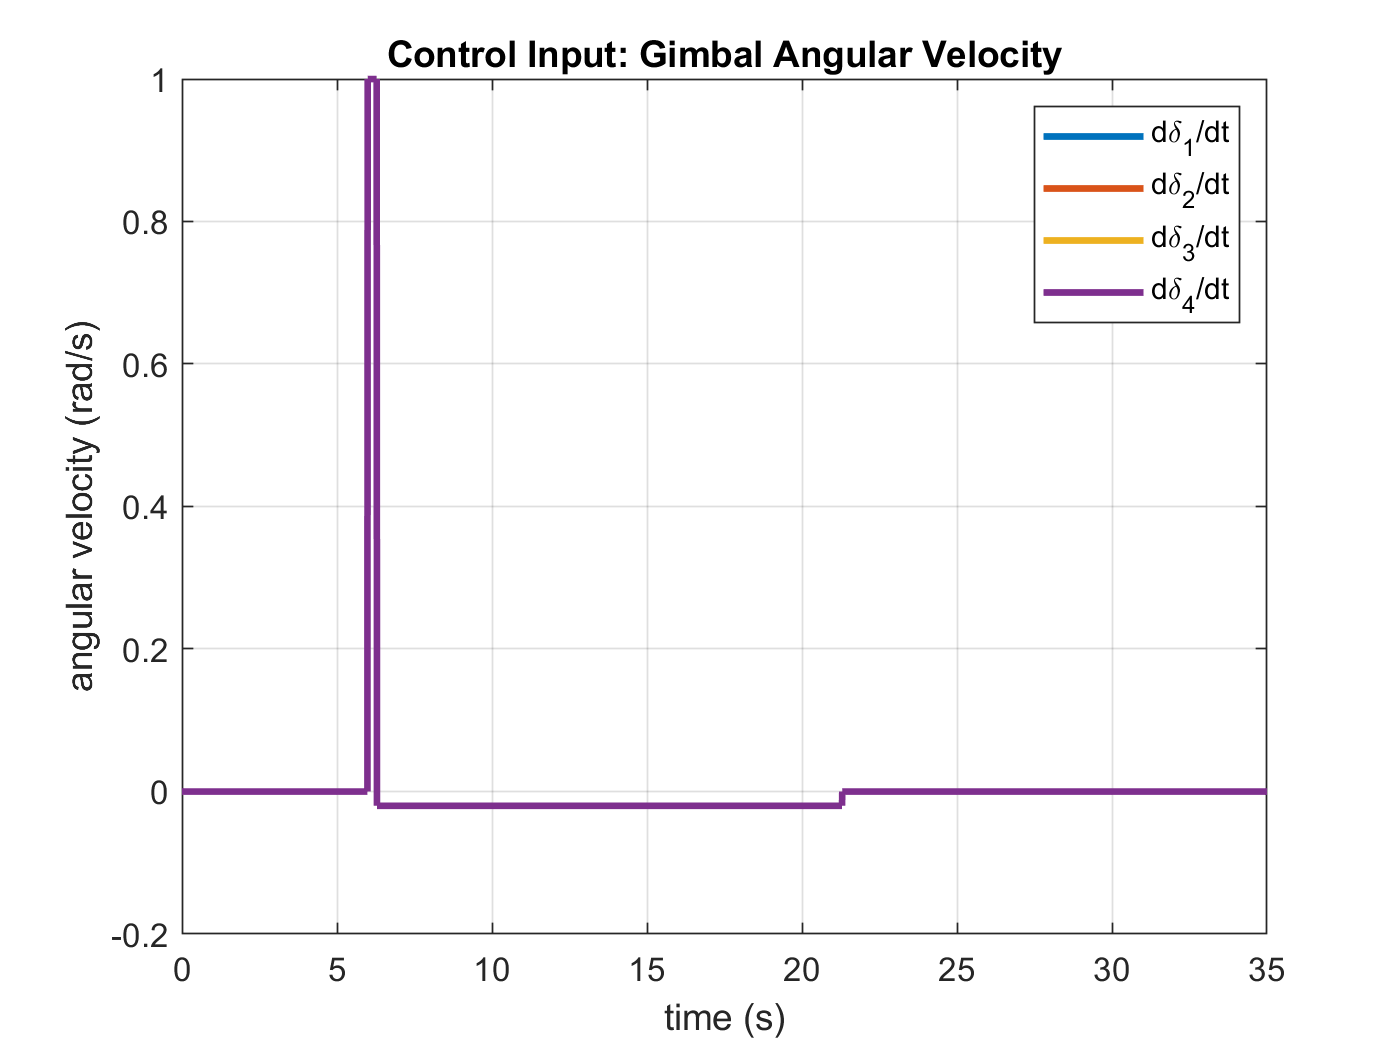

pulse_dur = 1;

pulse_mag = [];
pulse_mag = [1*ones(30,1);-0.02*ones(1500,1)];

delta_dot = zeros(4,length(tspan));
ind = 600;
for i = 1:length(pulse_mag)
    delta_dot(:,ind:ind+pulse_dur) = pulse_mag(i)*ones(4,pulse_dur+1);
    ind = ind+pulse_dur;
end

input_dir = [ 1  0  0  0;
              0  1  0  0;
              0  0  1  0;
              0  0  0  1];
delta_dot = input_dir*delta_dot;

figure
plot(tspan,delta_dot,'LineWidth',2)
title('Control Input: Gimbal Angular Velocity')
xlabel('time (s)')
ylabel('angular velocity (rad/s)')
legend(['d\delta_1/dt'],'d\delta_2/dt','d\delta_3/dt','d\delta_4/dt')
grid on

## Simulation

We will simulate the spacecraft dynamics using ode45. A more detailed explanation of the system dynamics is provided inside *dynamics.mlx*. As a general overview, we will provide an intial state to the integrator (ode45) along with a timespan and out control sequence. ode45 will then return our states evaluated at each timestep. Our states, as defined in our initial conditions above, are gimbal angular postion and spacecraft angular velocity. Because we are also interested in the angular positon of the spacecraft, we will send the spacecraft angular velocity into a post-process integrator (also contained in an ode45 operation.

x0 = [delta;
      omega];
% [t,x] = ode45(dynamicsWrapper,tspan,x0,[],tspan,delta_dot);

[t,x] = ode45(@(t,x) dynamics(t, x, tspan, delta_dot), tspan, x0); % Solve ODE

[~,ang] = ode45(@(t,ang) integrator(t, ang, tspan, x(:,5:7)'), tspan, [0;0;0]);
roll = ang(:,1);
pitch = ang(:,2);
yaw = ang(:,3);

## Visualization

Below, we will generate plots and an animation to help visualize the system dynamics.

### Spacecraft Angular Velocity

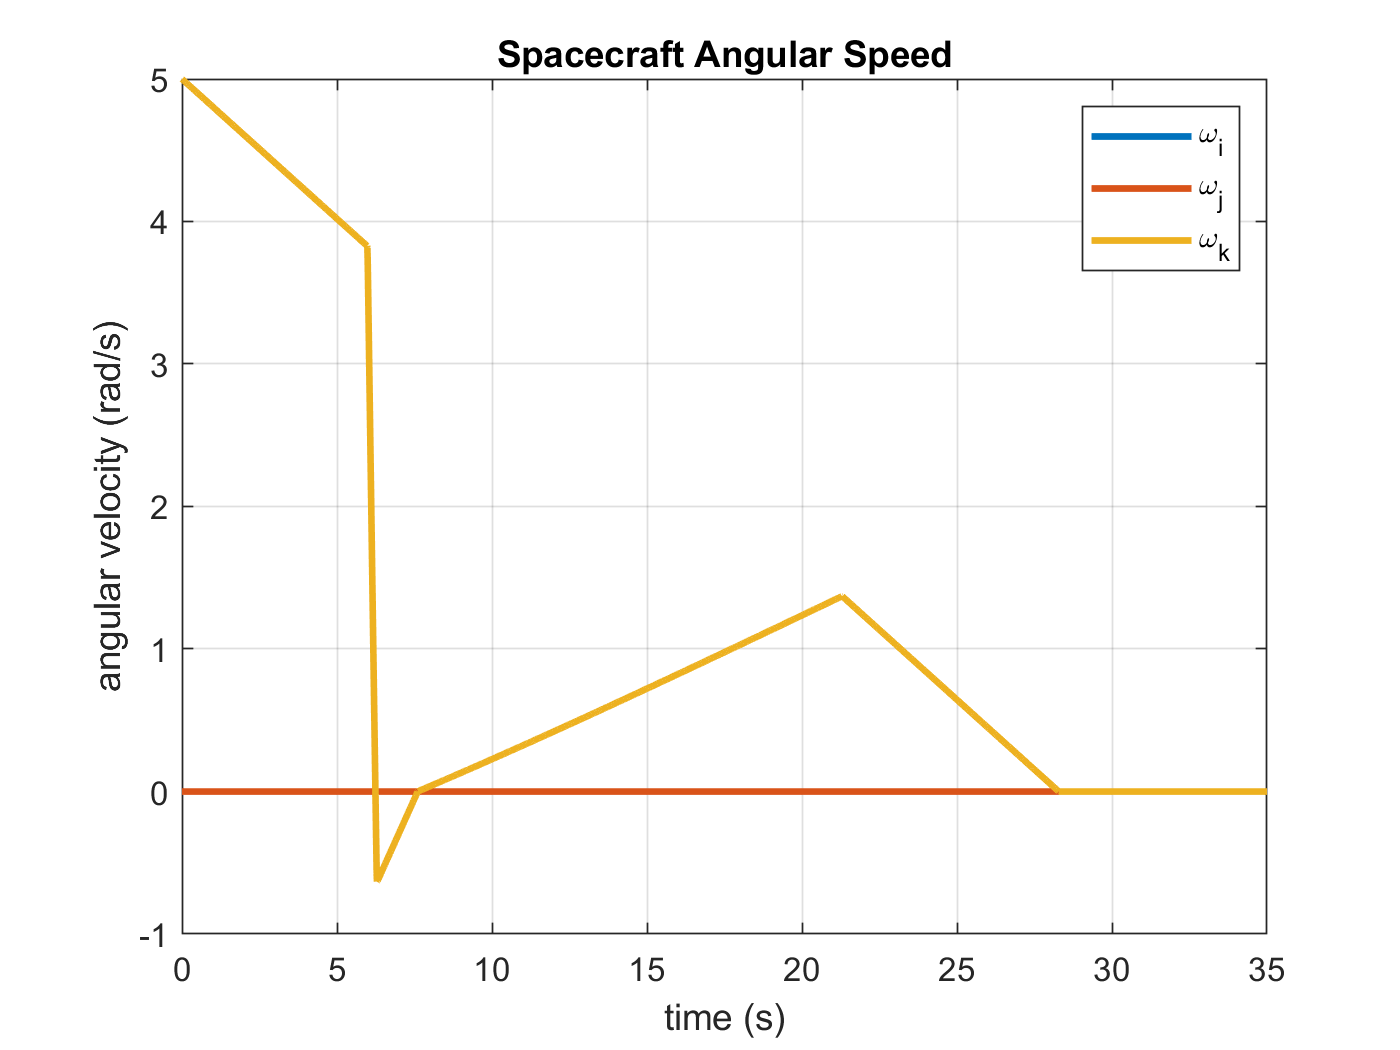

figure
plot(tspan,x(:,5:7),'LineWidth',2)
title('Spacecraft Angular Speed')
xlabel('time (s)')
ylabel('angular velocity (rad/s)')
legend('\omega_i','\omega_j','\omega_k')
grid on

### Gimbal Angle

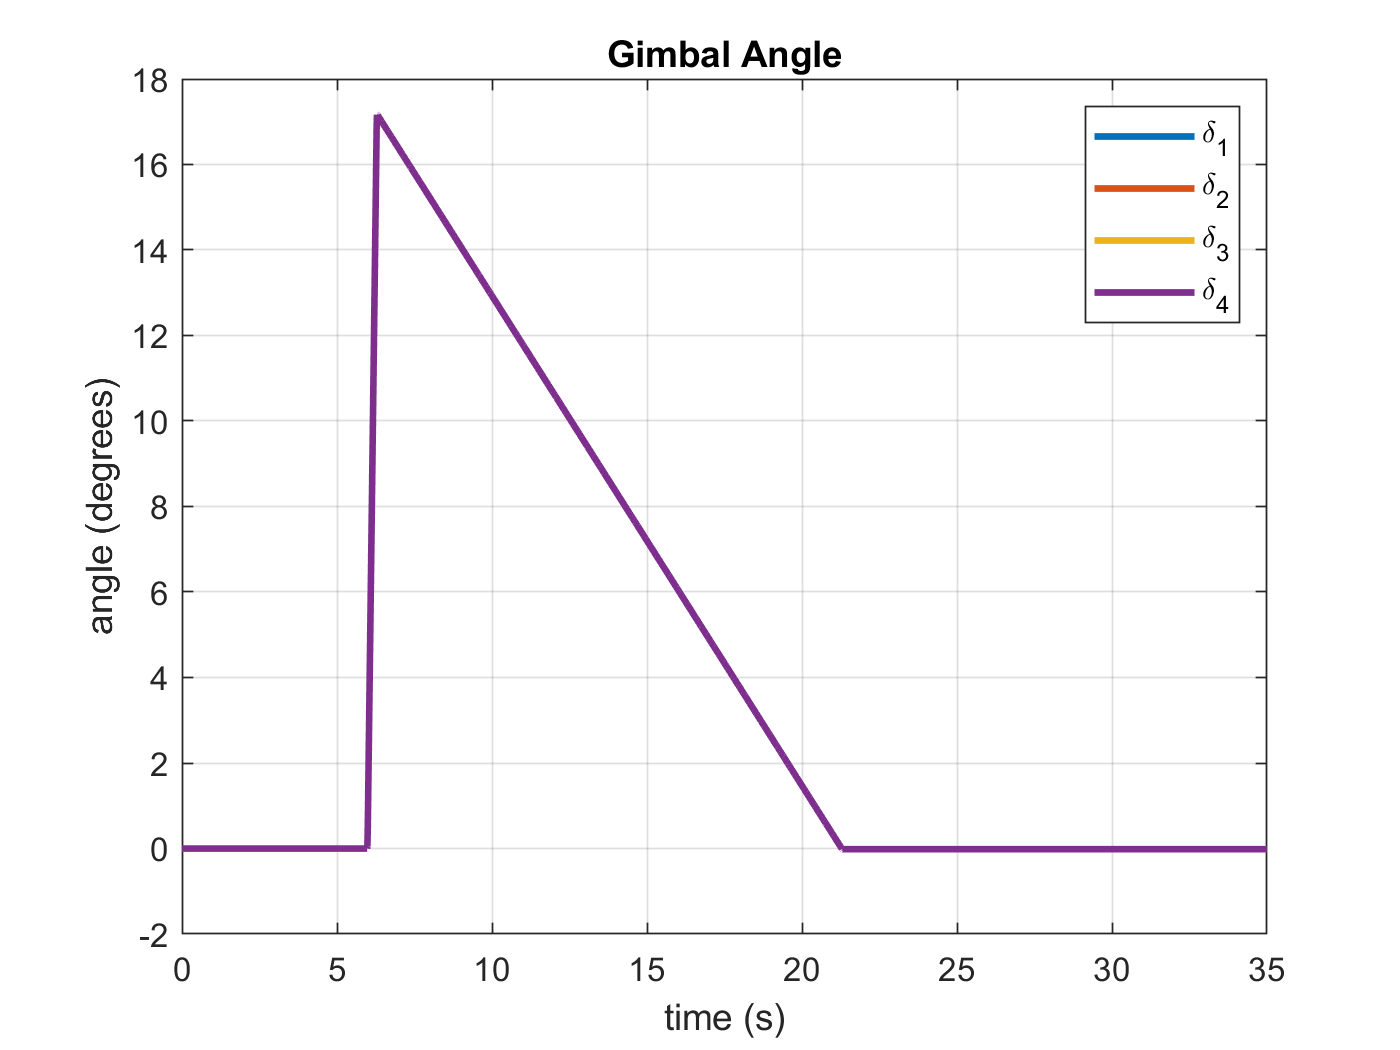

figure
plot(tspan,rad2deg(x(:,1:4)),'LineWidth',2)
title('Gimbal Angle')
xlabel('time (s)')
ylabel('angle (degrees)')
legend('\delta_1','\delta_2','\delta_3','\delta_4')
grid on

### Spacecraft Angular Position

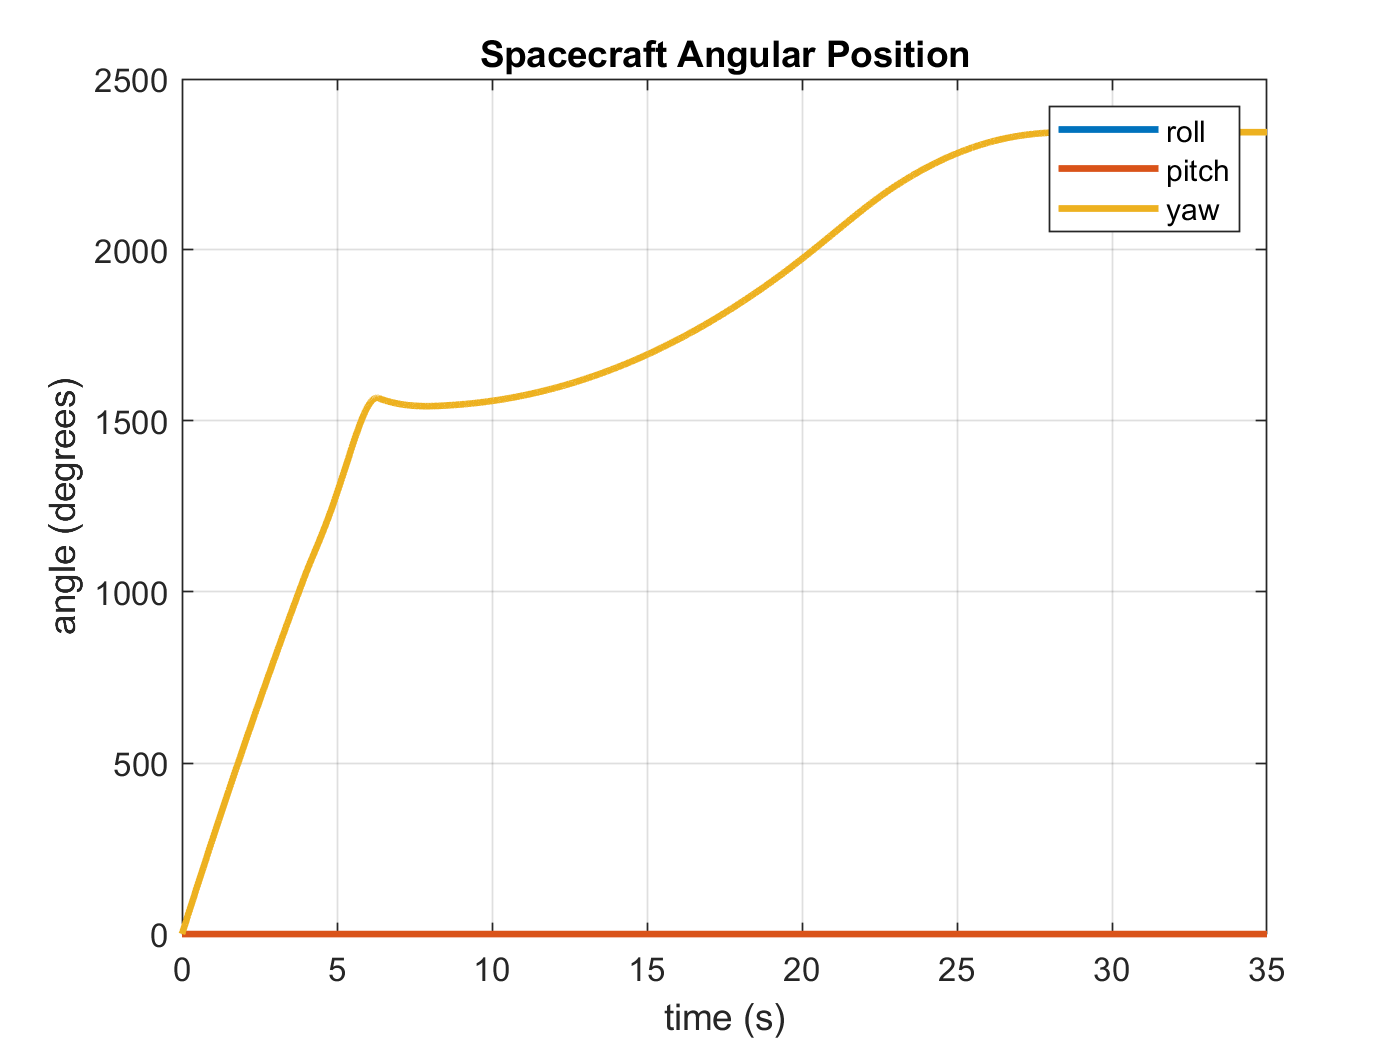

figure
plot(tspan,rad2deg(roll),'LineWidth',2)
hold on
plot(tspan,rad2deg(pitch),'LineWidth',2)
plot(tspan,rad2deg(yaw),'LineWidth',2)
title('Spacecraft Angular Position')
xlabel('time (s)')
ylabel('angle (degrees)')
legend('roll','pitch','yaw')
grid on

### Spacecraft Angular Position

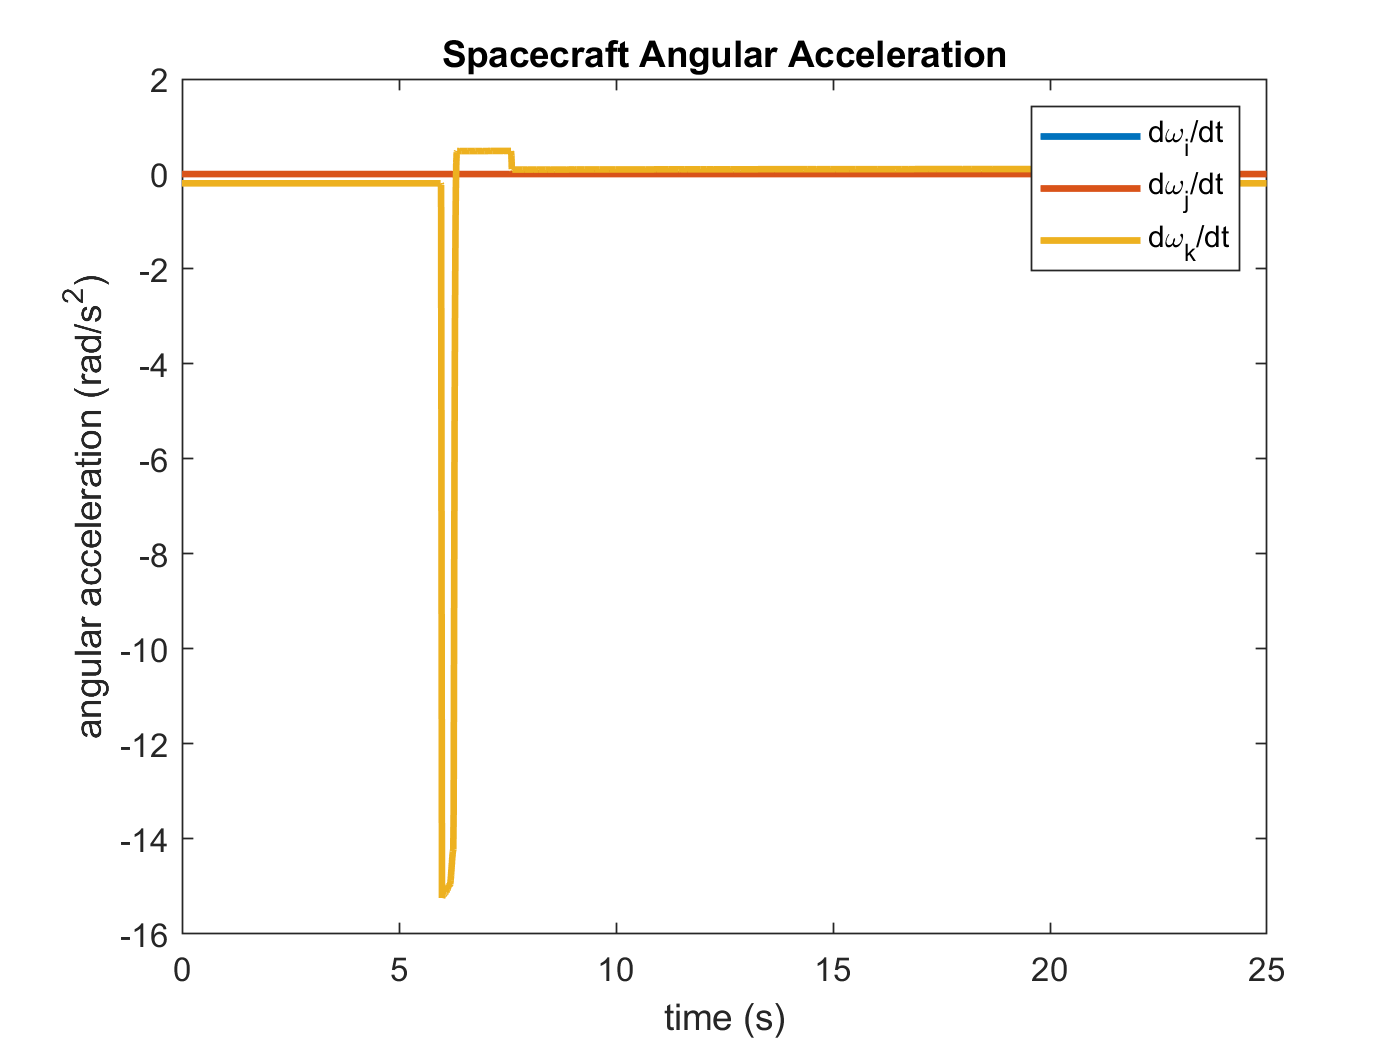

angAcc_x = diff(x(:,5))/dt;
angAcc_y = diff(x(:,6))/dt;
angAcc_z = diff(x(:,7))/dt;

figure
plot(t(1:end-1),angAcc_x,'LineWidth',2)
hold on
plot(t(1:end-1),angAcc_y,'LineWidth',2)
plot(t(1:end-1),angAcc_z,'LineWidth',2)
title('Spacecraft Angular Acceleration')
xlabel('time (s)')
ylabel('angular acceleration (rad/s^2)')
legend('d\omega_i/dt','d\omega_j/dt','d\omega_k/dt')

### Animate

We will use a visualizaion tool to see how the spacecraft changes attitude during simulation.

% spacecraft does not translate, so fix x, y, and z during animation
x_ = zeros(1,length(tspan));
y_ = zeros(1,length(tspan));
z_ = zeros(1,length(tspan));

% spacecraft_Animation(x_,y_,z_,rad2deg(roll),rad2deg(pitch),rad2deg(yaw))

## References

[1] Wie, Bong & Bailey, David & Heiberg, Christopher. (2001). Singularity Robust Steering Logic for Redundant Single-Gimbal Control Moment Gyros. Journal of Guidance Control and Dynamics - J GUID CONTROL DYNAM. 24. 865-872. 10.2514/2.4799. 